run AircraftData.mlx

Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]



%Flight Conditions
V = 375; %kts 
h = 25000; %ft
DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
MTOW = Vanguard.MTOW;
W = MTOW*0.946;

[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688

V = 633

M = V/SpeedSound

M = 0.6233


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = Vanguard.Wing.Airfoil.TMax

Tmax = 0.1500

LocMaxT = Vanguard.Wing.Airfoil.LocTMax

LocMaxT = 0.4000

PerLamFlow = Vanguard.Wing.Airfoil.PerLamFlow

PerLamFlow = 0.1000

CLDMin = Vanguard.Wing.Airfoil.CldMin

CLDMin = 0.1000


%Planform Parameters
S = Vanguard.Wing.S; %ft^2
b = Vanguard.Wing.b;
AR = Vanguard.Wing.AR;
TaperRatio = Vanguard.Wing.TaperRatio;
Q = 1.01

Q = 1.0100

SweepQuartC = Vanguard.Wing.QuarterChordSweep;

%Fuselage Parameters
Df = Vanguard.Fuselage.Diameter; %ft
LNose = Vanguard.Fuselage.NoseLength; %ft
LMid = Vanguard.Fuselage.CargoLength; %ft
LTail = Vanguard.Fuselage.TailLength %ft

LTail = 37.0910

DBase = Vanguard.Fuselage.BaseDia %ft

DBase = 4

ABase = Vanguard.Fuselage.ABase

ABase = 12.5664

UpsweepAngle = Vanguard.Fuselage.UpsweepAngle; %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = Vanguard.VerticalTail.S; %ft^2
ARv = Vanguard.VerticalTail.AR;
TaperRatiov = Vanguard.VerticalTail.TaperRatio;
bv = Vanguard.VerticalTail.b;
QVt = 1.05;
LocMaxTv = Vanguard.VerticalTail.LocTMax;
Tmaxv = Vanguard.VerticalTail.TMax

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = Vanguard.HorizontalTail.S; %ft^2
ARh = Vanguard.HorizontalTail.AR;
TaperRatioh = Vanguard.HorizontalTail.TaperRatio;
bh = Vanguard.HorizontalTail.b;
QHt = 1.05;
LocMaxTh = Vanguard.HorizontalTail.LocTMax;
Tmaxh = Vanguard.HorizontalTail.TMax

Tmaxh = 0.1200


%Nacelle Parameters
LNacelle = 9.3;
DNacelle = 5.2;

%Blister Parameters
LBlister = 16;
DBlister = 3;

%Induced Drag Factor

Ne = 0; %Num of engines ON TOP of Wing
TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)

TaperFunc = 0.0053

K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR);
e = 1/(K*AR*pi);

[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 90
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


V = 1.0685e+03

M = 1.0521

Cr = 17.3433

Cmac = 14.3954

Ymac = 25.2857

SweepMaxT = -1.7355

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 90
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Re = 8.5882e+07

SweepMaxT = -1.7355

Cf = 0.0021

FF = 1.7248

Swet = 2.8073e+03

CDo = 0.0063


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 90
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


V = 1.0685e+03

M = 1.0521

Cr = 17.3433

Cmac = 14.3954

Ymac = 9.5530

SweepMaxT = -1.6531

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 90
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Re = 8.5882e+07

SweepMaxT = -1.6531

Cf = 0.0021

FF = 1.6583

Swet = 815.7600

CDo = 0.0075


CDoHt = CDoHt*Sh/S;

[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 90
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


V = 1.0685e+03

M = 1.0521

Cr = 17.3433

Cmac = 14.3954

Ymac = 10.3920

SweepMaxT = -1.8842

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 90
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Re = 8.5882e+07

SweepMaxT = -1.8842

Cf = 0.0021

FF = 1.6583

Swet = 1.2236e+03

CDo = 0.0075


CDoVt = CDoVt*Sv/S/2;

[CDoFuse] = 0.0068 %ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S);

CDoFuse = 0.0068


[CDoNacelle] = 4*ParaDragNacelle(h,V,LNacelle,DNacelle,DynVisc,S);

Re = 3.2869e+07

Cf = 0.0023

FF = 1.1957

SWet = 151.9274

CDo = 3.7869e-04


[CDoBlisters] = ParaDragNacelle(h,V,LBlister,DBlister,DynVisc,S);

Re = 5.6549e+07

Cf = 0.0021

FF = 1.0656

SWet = 150.7964

CDo = 3.0785e-04


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S;

CDoCamber = e/(1-e)*K*CLDMin^2;

BaseDrag = (0.1+0.1222*M^8)*ABase/S;

CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag + BaseDrag + CDoNacelle + CDoCamber;




CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2;
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
end

LDMax = 0.3944

LDMax = 0.7884

LDMax = 1.1815

LDMax = 1.5734

LDMax = 1.9636

LDMax = 2.3517

LDMax = 2.7373

LDMax = 3.1200

LDMax = 3.4994

LDMax = 3.8752

LDMax = 4.2469

LDMax = 4.6144

LDMax = 4.9771

LDMax = 5.3348

LDMax = 5.6872

LDMax = 6.0340

LDMax = 6.3750

LDMax = 6.7099

LDMax = 7.0384

LDMax = 7.3604

LDMax = 7.6756

LDMax = 7.9839

LDMax = 8.2851

LDMax = 8.5792

LDMax = 8.8658

LDMax = 9.1451

LDMax = 9.4168

LDMax = 9.6810

LDMax = 9.9374

LDMax = 10.1862

LDMax = 10.4274

LDMax = 10.6608

LDMax = 10.8865

LDMax = 11.1045

LDMax = 11.3149

LDMax = 11.5177

LDMax = 11.7129

LDMax = 11.9007

LDMax = 12.0811

LDMax = 12.2542

LDMax = 12.4201

LDMax = 12.5789

LDMax = 12.7306

LDMax = 12.8756

LDMax = 13.0137

LDMax = 13.1452

LDMax = 13.2703

LDMax = 13.3889

LDMax = 13.5014

LDMax = 13.6077

LDMax = 13.7081

LDMax = 13.8028

LDMax = 13.8917

LDMax = 13.9752

LDMax = 14.0533

LDMax = 14.1262

LDMax = 14.1941

LDMax = 14.2570

LDMax = 14.3152

LDMax = 14.3687

LDMax = 14.4178

LDMax = 14.4625

LDMax = 14.5030

LDMax = 14.5395

LDMax = 14.5720

LDMax = 14.6008

LDMax = 14.6259

LDMax = 14.6474

LDMax = 14.6656

LDMax = 14.6805

LDMax = 14.6922

LDMax = 14.7008

LDMax = 14.7066

LDMax = 14.7095

LDMax = 14.7097


Line1 = [0]

Line1 = 0


% K2 = 1/(0.987*pi*AR)
% 
% LDMax2 = 0;
% 
% for x=1:201
%     
%    CD2(x) = CDoTotal2 + K2*CL(x)^2;
%    
%    if CL(x)/CD(x)>LDMax2
%        
%        LDMax2 = CL(x)/CD2(x)
%        
%    end
%    
% end

plot (CD,CL)

xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on
grid minor
hold on
ax = gca;
ax.XLim = [0 0.1152]

ax =   Axes with properties:

             XLim: [0 0.1152]
             YLim: [-0.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1163 0.7750 0.8087]
            Units: 'normalized'

  Show all properties


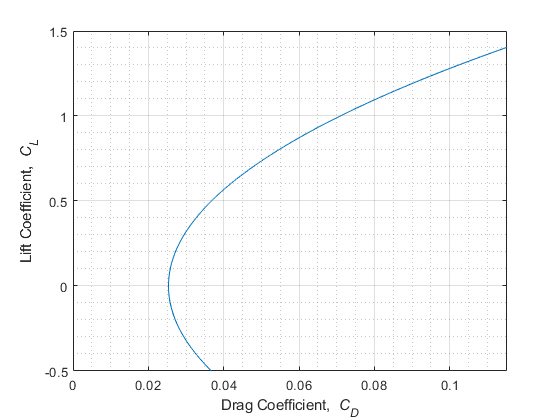

%ax.XAxisLocation = 'origin';
hold off

LDMax

LDMax = 14.7097


DynViscSL = 3.737*10^(-7)

DynViscSL = 3.7370e-07

Swf = 1100

Swf = 1100

%%%%%%%%%%%%%%%%%%%%%
% Landing and Takeoff
%%%%%%%%%%%%%%%%%%%%%

[CDoWingSL] = WingZeroLiftDrag(100,Q,TaperRatio,DynViscSL,0,S,AR,b,0,LocMaxT,Df,PerLamFlow,Tmax);

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 90
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


V = 168.8000

M = 0.1513

Cr = 17.3433

Cmac = 14.3954

Ymac = 25.2857

SweepMaxT = -1.7355

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 90
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Re = 2.6089e+07

SweepMaxT = -1.7355

Cf = 0.0023

FF = 1.2165

Swet = 2.8073e+03

CDo = 0.0049


[CDoHtSL] = WingZeroLiftDrag(100,QHt,TaperRatioh,DynViscSL,0,Sh,ARh,bh,0,LocMaxTh,0,PerLamFlow,Tmaxh);

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 90
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


V = 168.8000

M = 0.1513

Cr = 17.3433

Cmac = 14.3954

Ymac = 9.5530

SweepMaxT = -1.6531

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 90
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Re = 2.6089e+07

SweepMaxT = -1.6531

Cf = 0.0023

FF = 1.1696

Swet = 815.7600

CDo = 0.0059


CDoHtSL = CDoHtSL*Sh/S

CDoHtSL = 0.0014


[CDoVtSL] = WingZeroLiftDrag(100,QVt,TaperRatiov,DynViscSL,0,Sv,ARv,bv,0,LocMaxTv,0,PerLamFlow,Tmaxv);

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 90
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


V = 168.8000

M = 0.1513

Cr = 17.3433

Cmac = 14.3954

Ymac = 10.3920

SweepMaxT = -1.8842

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 90
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 90
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Re = 2.6089e+07

SweepMaxT = -1.8842

Cf = 0.0023

FF = 1.1696

Swet = 1.2236e+03

CDo = 0.0059


CDoVtSL = CDoVtSL*Sv/S/2;

[CDoFuseSL] = ParaDragFuse(0,100,LMid,LNose,LTail,Df,DynViscSL,S);

Cf = 0.0021

FF = 1.2642

SWet = 4.1690e+03

CDo = 0.0068


[CDoNacelleSL] = 4*ParaDragNacelle(0,100,LNacelle,DNacelle,DynViscSL,S);

Re = 9.9849e+06

Cf = 0.0027

FF = 1.1957

SWet = 151.9274

CDo = 4.5511e-04


[CDoBlistersSL] = ParaDragNacelle(0,100,LBlister,DBlister,DynViscSL,S);

Re = 1.7178e+07

Cf = 0.0025

FF = 1.0656

SWet = 150.7964

CDo = 3.6866e-04

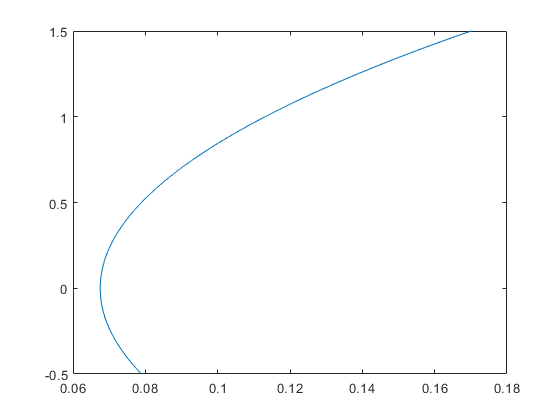


CDo_CleanSL = CDoWingSL + CDoHtSL + CDoVtSL + CDoFuseSL + UpSweepDrag + BaseDrag + CDoNacelleSL + CDoCamber;

k1 = 1.75;

k2Landing = 0.0375;

k2TO = 0.0125;

dCDoLanding = k1*k2Landing*Swf/S;

dCDoTO = k1*k2TO*Swf/S;

for x=1:201
    
   CDLanding(x) = CDo_CleanSL+dCDoLanding + K*CL(x)^2;

   CDTO(x) = CDo_CleanSL+dCDoTO + K*CL(x)^2;
    
end



plot (CDLanding,CL)

plot (CDTO,CL)

legend('Cruise','Landing', 'Takeoff')

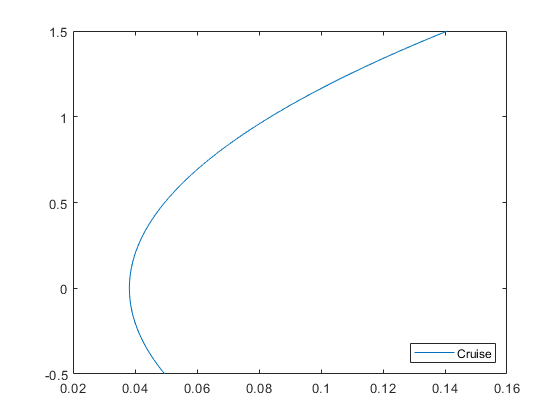

legend('Location','southeast')

hold off